# 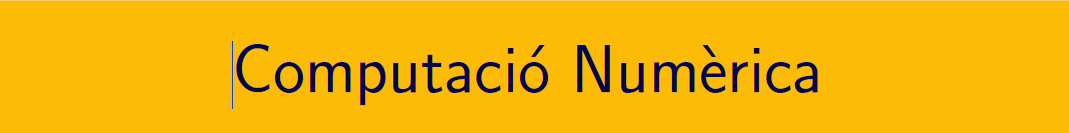

================================================================================

# Pràctica 12. Equacions diferencials ordinàries (I).

`Document preparat per M. Àngela Grau Gotés - 17 de maig de 2023`

## APRENEM... 

## **PVI  **$y^{\prime}=t\sqrt{y},\quad y(1)=4,\quad 1\leq t\leq 2\,.$

### MATLAB® - Solució analítica 

Consulteu l'ajuda de la comanda [DSOLVE](https://es.mathworks.com/help/symbolic/dsolve.html)

syms y(t)
eqn = diff(y,t) == t*y;
cond = y(1) == 4;
ySol(t) = dsolve(eqn,cond) 

$$ySol(t) = 4\,{\mathrm{e}}^{-\frac{1}{2}}\,{\mathrm{e}}^{\frac{t^{2}}{2}}$$

% ySol(t)=0.0625*(7+t^2)^2

La solució es pot respresentar a l'interval [1,2]

% fplot(ySol,[1,2])

**Isoclines del camp de direccions y'=f(t,y)**

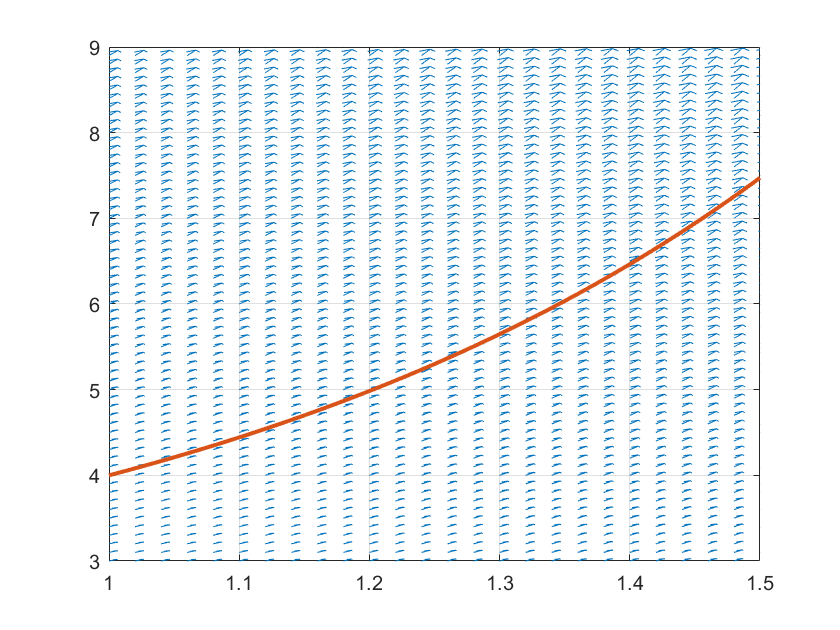

t=1:0.02:1.5; 
y=3:0.1:9;
[TT,YY] = meshgrid(t,y);
DT = ones(size(TT));
f = @(t,y)t.*(y);
DY = f(TT,YY);
% Gràfic
figure(1)
quiver(TT,YY,DT,DY);grid,axis([1,1.5,3,9]), hold on
fplot(ySol,[1,2],'LineWidth',2), hold off

### Solucions aproximades numèricament

#### `Metode d'Euler`

$$y'= f(t,y)$$  amb valors inicials $$y(a) = \alpha$$.

Pas 1: discretitzar l'interval entre $$a$$ i $$b$$. Creem $$N$$ nodes $$T_i = a + ih$$ amb $$h = \frac{b-a}{N}$$  

Pas 2: Si denotem $$w_i \approx y(t_i)$$, generem els valors mitjançant la recurrència $$w_0 = \alpha$$, $$w_{i+1} = w_i + h\cdot f(t_i, w_i)$$

#### `Mètode d'Euler per h = 0.2, h = 0.1 ....`

close all;
a = 1; alpha = 4;    % y(a) = alpha
b = 2;               % y(b) = ...

f = @(t,y) t*y;
h= 0.05;

[ Y1, t1 ] = Euler( f,a,b,h,alpha );
disp(array2table([t1;Y1]','VariableNames',{'t_k','Y_k'}))

    t_k           Y_k       
    ____    ________________

       1                   4
    1.05                 4.2
     1.1              4.4205
    1.15           4.6636275
     1.2       4.93178608125
    1.25      5.227693246125
     1.3    5.55442407400781
    1.35    5.91546163881832
     1.4    6.31475529943856
    1.45    6.75678817039926
     1.5     7.2466553127532
    1.55    7.79015446120969
     1.6    8.39389143195344
    1.65    9.06540274650972
     1.7    9.81329847309677
    1.75      10.64742884331
     1.8    11.5790788670996
    1.85    12.6211959651386
     1.9    13.7886565919139
    1.95    15.0985789681457
       2    16.5706904175399



y2 = double(ySol(b)); % solucio exacte
y_exacte = double(ySol(t1));
errorlocal =  abs(y_exacte - Y1)    % error al llarg del metode

errorlocal =                    0   0.010344027577423   0.022342441422820   0.036287207072158   0.052520841099523   0.071445788790462   0.093535604662824   0.119348301326852   0.149542309333016   0.184895584832887   0.226328516975687   0.274931427809670   0.331997630039361   0.399063219737151   0.477955041256534   0.570848581638911   0.680337946072388   0.809520552327674   0.962099782906160   1.142509576848951   1.356065863812322


errorGlobal = abs(y2 - Y1(end))     % error al final del metodes

errorGlobal =    1.356065863812322


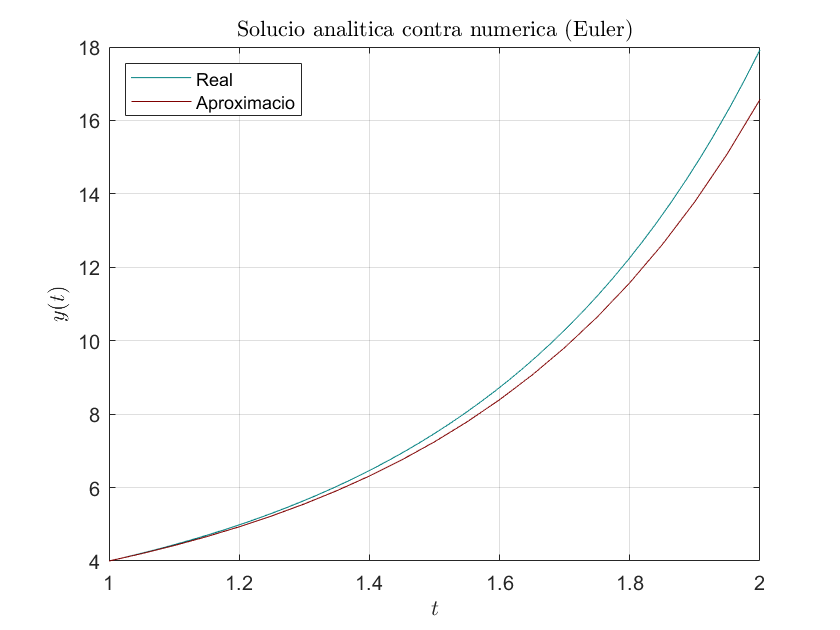

fplot(ySol, [1,2],'Color', [0 0.5 0.5])
hold on
plot(t1,Y1, 'Color', [0.5 0 0])
legend('Real', 'Aproximacio', 'Location','northwest')
title('Solucio analitica contra numerica (Euler)', 'Interpreter','latex')
xlabel('$t$', 'Interpreter', 'latex')
ylabel('$y(t)$', 'Interpreter', 'latex')
grid on
hold off

close all
% anem a veure els errors en funcio de h
err = []


err =

     []



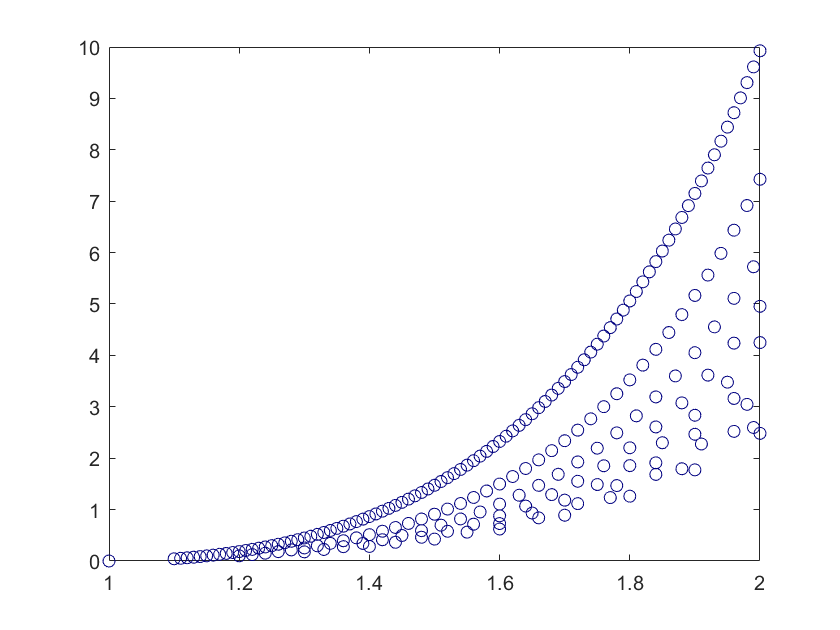

for hh = 0.1:0.01:1.00
    [ Y1, t1 ] = Euler( f,a,b,hh,alpha );
    y_exacte = double(ySol(t1));
    errorlocal =  abs(y_exacte - Y1);   % error al llarg del metode
    plot(t1, errorlocal, 'o', 'Color', [0 0 0.5])
    hold on
    err = [err; errorGlobal];
end

#### `Mètode d'Euler modificat`

close all;
a = 1; alpha = 4;      % y(a) = alpha
b = 2;               % y(b) = ...
h = 0.1

h =    0.100000000000000



[ YM1, t1 ] = EulerMod( f,a,b,h,alpha );
disp(array2table([t1;YM1]','VariableNames',{'t_k','Y_k'}))

    t_k          Y_k       
    ___    ________________

      1                   4
    1.1               4.441
    1.2         4.979804325
    1.3     5.6396283980625
    1.4    6.45046597099394
    1.5    7.45125576639365
    1.6    8.69282125846899
    1.7    10.2418820067282
    1.8    12.1865593527557
    1.9    14.6439790462389
      2     17.770834672087



y2 = double(ySol(b)); % solucio exacte
y_exacte = double(ySol(t1));
errorlocal =  abs(y_exacte - YM1)    % error al llarg del metode

errorlocal =                    0   0.001842441422821   0.004502597349523   0.008331280608136   0.013831637777638   0.021728063335244   0.033067803523817   0.049371507625143   0.072857460416337   0.106777328581213   0.155921609265253


errorGlobal = abs(y2 - YM1(end))     % error al final del metodes

errorGlobal =    0.155921609265253


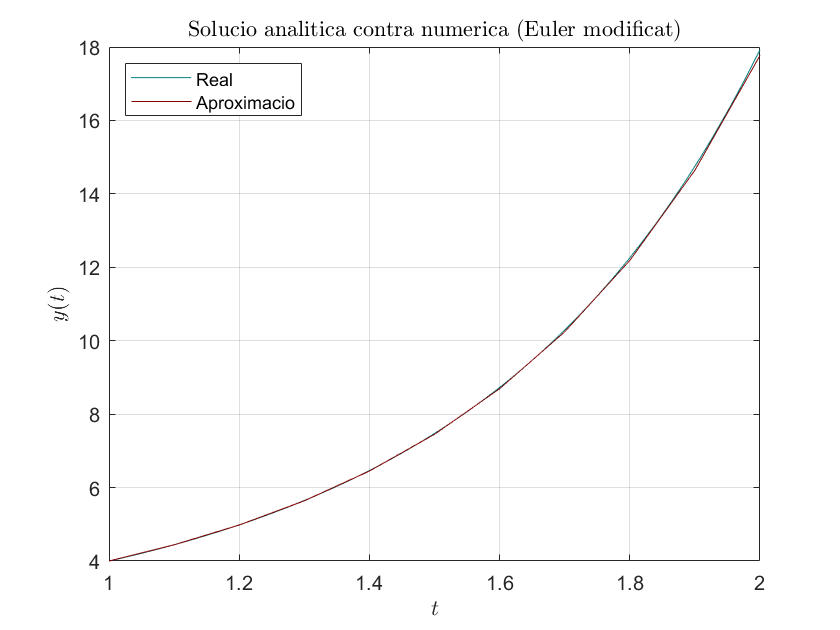

fplot(ySol, [1,2],'Color', [0 0.5 0.5])
hold on
plot(t1,YM1, 'Color', [0.5 0 0])
legend('Real', 'Aproximacio', 'Location','northwest')
title('Solucio analitica contra numerica (Euler modificat)', 'Interpreter','latex')
xlabel('$t$', 'Interpreter', 'latex')
ylabel('$y(t)$', 'Interpreter', 'latex')
grid on
hold off

#### `Mètode de Heun (Euler millorat)`

a = 1; alpha = 4;      % y(a) = alpha
b = 2;               % y(b) = ...

h = 0.1

h =    0.100000000000000



[ YH1,t1_h ] = EulerMill( f,a,b,h,alpha );
disp(array2table([t1;YM1]','VariableNames',{'t_k','Y_k'}))

    t_k          Y_k       
    ___    ________________

      1                   4
    1.1               4.441
    1.2         4.979804325
    1.3     5.6396283980625
    1.4    6.45046597099394
    1.5    7.45125576639365
    1.6    8.69282125846899
    1.7    10.2418820067282
    1.8    12.1865593527557
    1.9    14.6439790462389
      2     17.770834672087



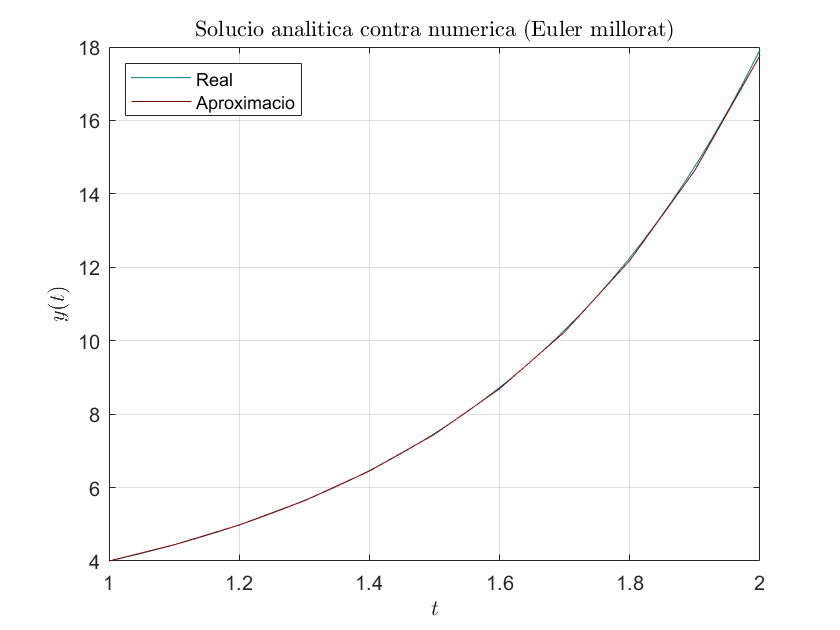

y2 = double(ySol(b)); % solucio exacte
y_exacte = double(ySol(t1_h));
fplot(ySol, [1,2],'Color', [0 0.5 0.5])
hold on
plot(t1,YM1, 'Color', [0.5 0 0])
legend('Real', 'Aproximacio', 'Location','northwest')
title('Solucio analitica contra numerica (Euler millorat)', 'Interpreter','latex')
xlabel('$t$', 'Interpreter', 'latex')
ylabel('$y(t)$', 'Interpreter', 'latex')
grid on
hold off


errorlocal_h =  abs(y_exacte - YH1)    % error al llarg del metode

errorlocal_h =                    0   0.000842441422821   0.002159722349523   0.004183330510636   0.007253088841717   0.011868886949941   0.018767923769770   0.029040540843637   0.044304710803450   0.066970116562823   0.100639763827967


plot(t1_h,errorlocal_h)
hold on
h = 0.05 % h/2

h =    0.050000000000000


[ YH1_m,t1_m ] = EulerMill( f,a,b,h,alpha );
y_exacte_m = double(ySol(t1_m));
errorlocal_hm =  abs(y_exacte_m - YH1_m)    % error al llarg del metode

errorlocal_hm =                    0   0.000094027577423   0.000212955485321   0.000362404676036   0.000549194465995   0.000781600459286   0.001069669229140   0.001425602619965   0.001864227544105   0.002403570887353   0.003065563787483   0.003876905339531   0.004870122998778   0.006084875960898   0.007569559058068   0.009383278800701   0.011598290852691   0.014303010386151   0.017605734604462   0.021639251755825   0.026566555101528


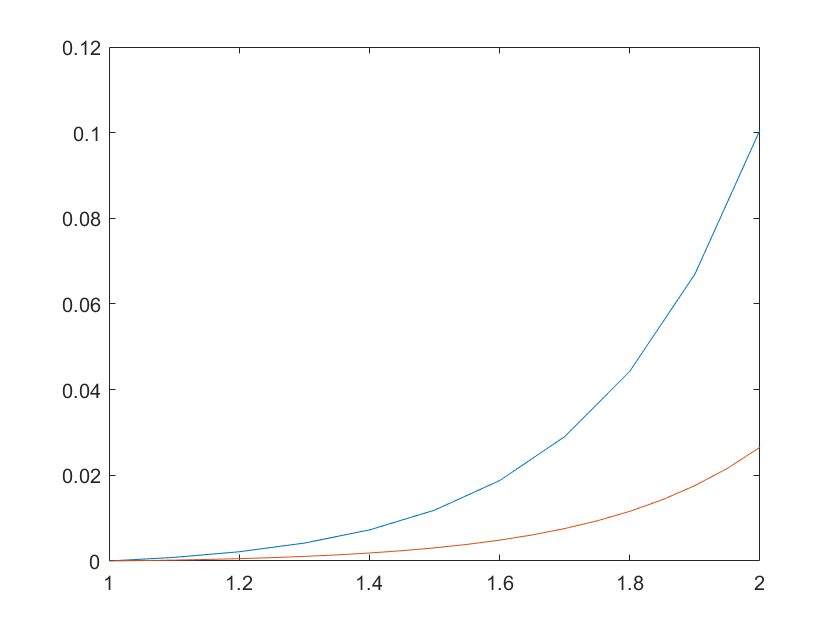

plot(t1_m,errorlocal_hm)
hold off

#### `Mètode RK4`

a = 1; alpha = 4;      % y(a) = alpha
b = 2;               % y(b) = ...
h = 0.1

h =    0.100000000000000




[ YK1,t1_h ] = RK4( f,a,b,h,alpha );
disp(array2table([t1_h;YK1]','VariableNames',{'t_k','Y_k'}))

    t_k          Y_k       
    ___    ________________

      1                   4
    1.1        4.4428419625
    1.2    4.98430556466454
    1.3    5.64795676462594
    1.4    6.46429200743135
    1.5    7.47297367471257
    1.6    8.72587129872686
    1.7    10.2912231735976
    1.8    12.2593658446271
    1.9    14.7506717720446
      2     17.926617061851



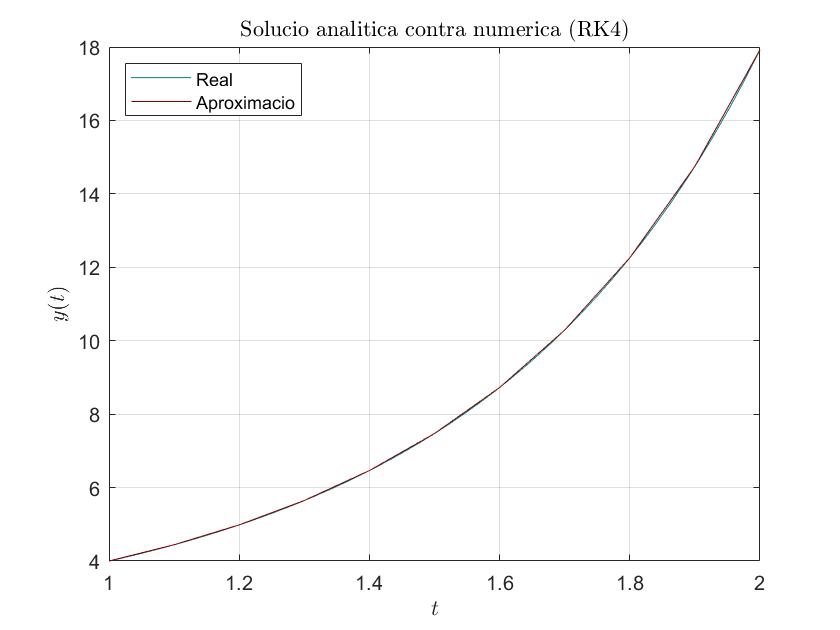

y2 = double(ySol(b)); % solucio exacte
y_exacte = double(ySol(t1_h));
fplot(ySol, [1,2],'Color', [0 0.5 0.5])
hold on
plot(t1_h,YK1, 'Color', [0.5 0 0])
legend('Real', 'Aproximacio', 'Location','northwest')
title('Solucio analitica contra numerica (RK4)', 'Interpreter','latex')
xlabel('$t$', 'Interpreter', 'latex')
ylabel('$y(t)$', 'Interpreter', 'latex')
grid on
hold off


errorlocal_h =  abs(y_exacte - YK1)    % error al llarg del metode

errorlocal_h = 	1.0e+-3 *

                   0   0.000478922820513   0.001357684980441   0.002914044695324   0.005601340221872   0.010155016319402   0.017763265946158   0.030340755706959   0.050968544927699   0.084602775450193   0.139219501278376


plot(t1_h,errorlocal_h)
hold on
h = 0.05 % h/2

h =    0.050000000000000


[ YK1_m,t1_m ] = RK4( f,a,b,h,alpha );
y_exacte_m = double(ySol(t1_m))i;
errorlocal_hm =  abs(y_exacte_m - YK1_m)    % error al llarg del metode

errorlocal_hm = 	1.0e+-5 *

                   0   0.001257091231111   0.002993998116096   0.005363395327862   0.008561861797318   0.012841865970614   0.018526959433274   0.026031039812580   0.035882774707119   0.048756573622910   0.065511875391167   0.087242997715009   0.115342415973885   0.151581124008260   0.198210744173366   0.258093343674659   0.334866584594806   0.433153964429778   0.558832653396735   0.719374973812137   0.924284121239794


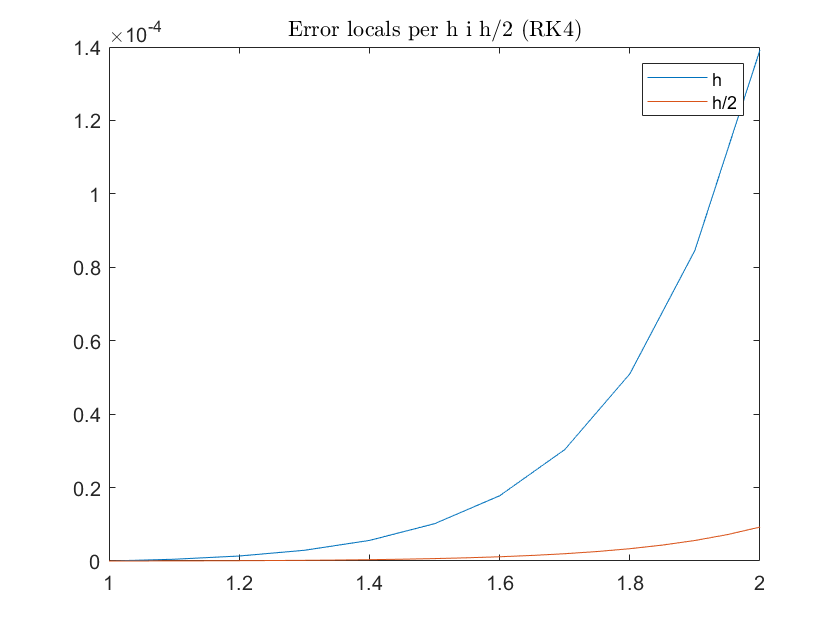

plot(t1_m,errorlocal_hm)    %??
title('Error locals per h i h/2 (RK4)', 'Interpreter','latex')
legend('h', 'h/2')
hold off

#### `Solvers de MATLAB®: ode23, ode45`

clearvars
syms y(t)
eqn = diff(y,t) == t*y;
cond = y(1) == 4;
ySol(t) = dsolve(eqn,cond) 

$$ySol(t) = 4\,{\mathrm{e}}^{-\frac{1}{2}}\,{\mathrm{e}}^{\frac{t^{2}}{2}}$$


a = 1; alpha = 4; b = 2;
f = @(t,y) t.*y

f = function_handle with value:
    @(t,y)t.*y


tspan = [a b];
y0 = alpha

y0 =      4


[t0, y0] = ode23(f,tspan,y0)

t0 =    1.000000000000000
   1.080000000000000
   1.180000000000000
   1.280000000000000
   1.380000000000000
   1.480000000000000
   1.580000000000001
   1.680000000000001
   1.780000000000001
   1.880000000000001


y0 =    4.000000000000000
   4.347020765866667
   4.867008899036739
   5.503945030898130
   6.286765401201346
   7.253060414857083
   8.451928613231793
   9.947876713759904
  11.826181295171082
  14.200305869630034



disp(array2table([t0 y0],'VariableNames',{'t_k','Y_k'}))

    t_k           Y_k       
    ____    ________________

       1                   4
    1.08    4.34702076586667
    1.18    4.86700889903674
    1.28    5.50394503089813
    1.38    6.28676540120135
    1.48    7.25306041485708
    1.58    8.45192861323179
    1.68     9.9478767137599
    1.78    11.8261812951711
    1.88      14.20030586963
    1.98    17.2222268628197
       2    17.9214923450684



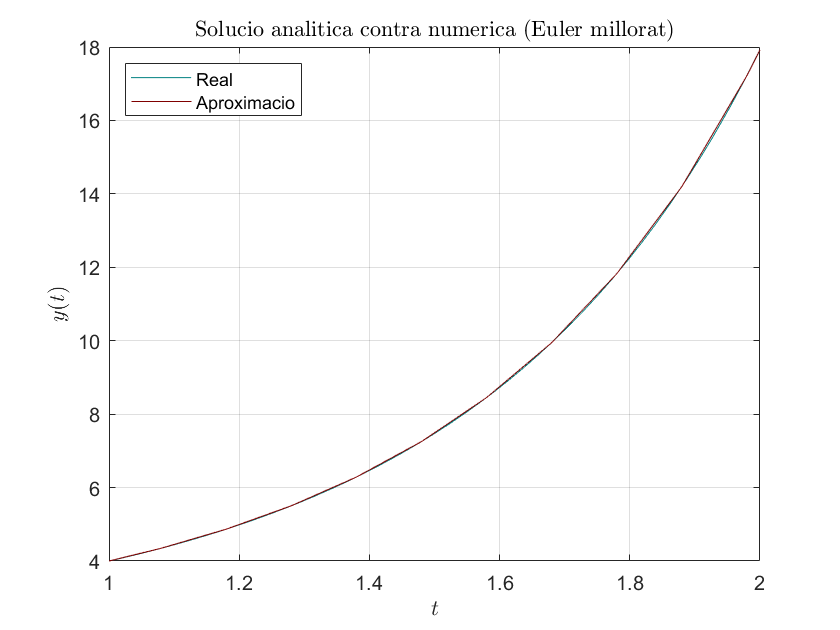

y2 = double(ySol(b)); % solucio exacte
y_exacte = double(ySol(t0));
fplot(ySol, [1,2],'Color', [0 0.5 0.5])
hold on
plot(t0,y0, 'Color', [0.5 0 0])
legend('Real', 'Aproximacio', 'Location','northwest')
title('Solucio analitica contra numerica (Euler millorat)', 'Interpreter','latex')
xlabel('$t$', 'Interpreter', 'latex')
ylabel('$y(t)$', 'Interpreter', 'latex')
grid on
hold off


% Plot solution
% plot(t1,y1,t2,y2)
% xlabel('t')
% ylabel('solution y')
% title('$y^{\prime}(t)=t\sqrt{y(t)}$','Interpreter¡','latex')

## PRACTIQUEM... 

### Exercici 1. 

 Resoleu els exercicis: 2,3,4,5,6,7, 8 i 11 del document practica12_edos_I.pdf disponible en el campus virtual.

#### **a) PVI  **$y^{\prime}(t)=-y(t)+t+1\,,\quad y(0)=1,\quad 0\leq t\leq 1\,.$

%% Respostes document --->  prac12_16maig_metodes_exercici_a.html   

#### **b) PVI  **$y^{\prime}(t)=te^{3t}-2y(t)\,,\quad y(0)=0,\quad 0\leq t\leq 1\,.$  

%% Respostes document --->  prac12_16maig_metodes_exercici_b.html   

#### **c) PVI  **$y^{\prime}(t)=\cos(2t)+\sin(3t)\,,\quad y(0)=1,\quad 0\leq t\leq 1\,.$

%% Respostes document --->  prac12_16maig_metodes_exercici_c.html   

### Exercici 2. 

Resoleu l'exercici 10 i 11 del document practica12_edos_I.pdf disponible en el campus virtual.

%% Respostes document --->  prac12_16maig_metodes_exercici_2.html   

function [ w,t ] = Euler(f,a,b,h,alpha)
% Mètode d'Euler
t=[a:h:b];
N=length(t);
w(1)=alpha;
for i=1:N-1
    w(i+1)=w(i)+h*f(t(i),w(i));
end
end
%-----------------------------------------
function  [w,t]  = EulerMod( f,a,b,h,alpha )
% Mètode d'Euler Modificat o punto medio
t=[a:h:b];
N=length(t);
w(1)=alpha;
for i=1:N-1
    k1 = w(i)+0.5*h*f(t(i),w(i) );
    w(i+1)=w(i)+h*f(t(i)+ h/2,k1);
end
end
%-----------------------------------------
function  [w,t]  = EulerMill( f,a,b,h,alpha )
% Mètode d'Euler Millorat o HEUN
    t=[a:h:b];
    N=length(t);
    w(1)=alpha;
    for i=1:N-1
        k1 = h*f(t(i),w(i) );
        k2 = h*f(t(i+1),w(i) +k1);
        w(i+1)=w(i)+0.5*(k1+k2);
    end
end
%----------------------------------------
function  [w,t]  = RK4( f,a,b,h,alpha )
% Mètode RK4
    t=[a:h:b];
    N=length(t);
    w(1)=alpha;
    for i=1:N-1
        k1 = h*f(t(i),w(i));
        k2 = h*f(t(i)+h/2,w(i) +k1/2);
        k3 = h*f(t(i)+h/2,w(i) +k2/2);
        k4 = h*f(t(i+1),w(i) +k3);
        w(i+1)=w(i)+(k1+2*k2+2*k3+k4)/6;
    end
end